# EXAMEN ARGUMENTATIVO

Raúl Correa Ocañas

A01722401

14 de junio de 2023

## PREGUNTA 9


clc
didt = @(t,i) (15*cos(150*t)/2 - R*i)/L; % eq dif
R = 50;
L = 0.1;
i(1) = 0; % q inicial
t_i = 0;
t_f = 4*pi/150;
h = (t_f-t_i)/100; % Paso delta h

[t,i_heun] = Heun(didt,t_i,t_f,i,h)

t =          0    0.0008    0.0017    0.0025    0.0034    0.0042    0.0050    0.0059    0.0067    0.0075    0.0084    0.0092    0.0101    0.0109    0.0117    0.0126    0.0134    0.0142    0.0151    0.0159    0.0168    0.0176    0.0184    0.0193    0.0201    0.0209    0.0218    0.0226    0.0235    0.0243    0.0251    0.0260    0.0268    0.0276    0.0285    0.0293    0.0302    0.0310    0.0318    0.0327    0.0335    0.0343    0.0352    0.0360    0.0369    0.0377    0.0385    0.0394    0.0402    0.0411


i_heun =          0    0.0494    0.0816    0.1015    0.1124    0.1166    0.1156    0.1107    0.1025    0.0917    0.0788    0.0643    0.0484    0.0315    0.0141   -0.0037   -0.0215   -0.0390   -0.0559   -0.0719   -0.0868   -0.1004   -0.1123   -0.1225   -0.1308   -0.1370   -0.1411   -0.1429   -0.1425   -0.1398   -0.1349   -0.1279   -0.1189   -0.1080   -0.0954   -0.0813   -0.0659   -0.0495   -0.0323   -0.0145    0.0034    0.0213    0.0388    0.0558    0.0719    0.0868    0.1003    0.1123    0.1225    0.1308


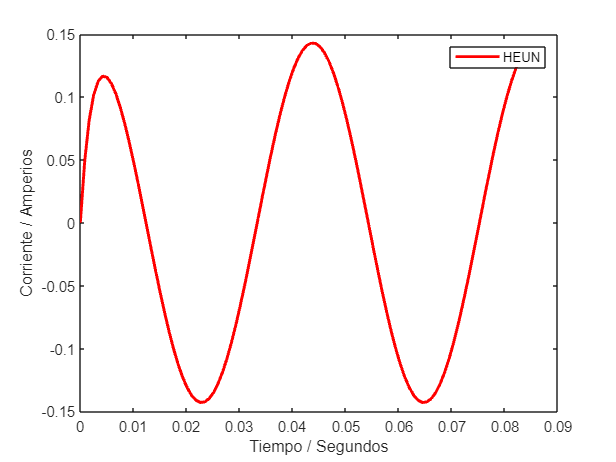


figure(1)
a1 = plot(t, i_heun, 'r', 'LineWidth', 2);
xlabel('Tiempo / Segundos')
ylabel('Corriente / Amperios')
legend(a1,'HEUN')

## Método de Heun

function [x,y] = Heun(f,t_1,t_f,y,h)
    x = t_1:h:t_f;
    for i = 1:length(x)-1
        k1 = f(x(i), y(i));
        k2 = f(x(i) + h, y(i) + k1*h);
        y(i+1) = y(i) + h*(k1 + k2)/2;
    end
end